clearvars;
% =========================================================================
% SIMULATION
% =========================================================================

% load the initial pressure distribution from an image and scale

PML_size = 20;              % size of the PML in grid points
Nx = 128 - 2 * PML_size;    % number of grid points in the x direction
Ny = 128 - 2 * PML_size;    % number of grid points in the y direction
x = 10e-3;                  % total grid size [m]
y = 10e-3;                  % total grid size [m]
dx = x / Nx;                % grid point spacing in the x direction [m]
dy = y / Ny;                % grid point spacing in the y direction [m]
kgrid = kWaveGrid(Nx, dx, Ny, dy);



load('./P0/P0001.mat')

% assign to the source structure
p0 = loadImage('')
source.p0 = p0*10;

% define the properties of the propagation medium
medium.sound_speed = 1500;  % [m/s]

% define a centered Cartesian circular sensor
sensor_radius = 4.9e-3;     % [m]
sensor_angle = 2*pi;      % [rad]
sensor_pos = [0, 0];        % [m]
num_sensor_points = 64;
cart_sensor_mask = makeCartCircle(sensor_radius, num_sensor_points, sensor_pos, sensor_angle);
% assign to sensor structure
mask = cart2grid(kgrid,cart_sensor_mask);
sensor.mask = mask;

% create the time array
kgrid.makeTime(medium.sound_speed);

% set the input options
input_args = {'Smooth', false, 'PMLInside', false, 'PlotPML', false, 'CreateLog', false};

% run the simulation
sensor_data = kspaceFirstOrder2D(kgrid, medium, source, sensor, input_args{:});

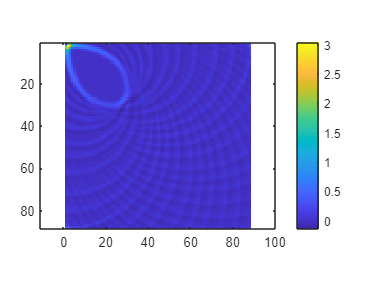

% load('./L0/L0001.mat')




SpeedofSound = medium.sound_speed; % [m/s]
                    % 记录时间 dt

dt = kgrid.dt;
 
% 传感器位置 r_i 二维数据（实际，标准（以坐标原点为中心）） % 2*len [x1,y1;x2,y2.....]
[sensor_location,~] =grid2cart(kgrid,sensor.mask);
sensor_location_x = sensor_location(1,:);
sensor_location_y = sensor_location(2,:);
 
% 重建图像位置 img_w*h，大小（实际，标准（以坐标原点为中心））
ImRecon = zeros(kgrid.Nx,kgrid.Ny);
p0_recon_location_x = kgrid.x;
p0_recon_location_y = kgrid.y;
 
a = zeros(64,88,88);

for i = 1:64

    % 计算每个信号到第i个传感器的距离
    distance_x = p0_recon_location_x - sensor_location_x(i);
    distance_y = p0_recon_location_y - sensor_location_y(i);
    distance_xy = sqrt(distance_y.^2 + distance_x.^2);
 
    % 计算传播需要时间
    distance_xy_time =  distance_xy./SpeedofSound;
 
    % 计算传播需要步长
    distance_xy_index = floor(distance_xy_time ./dt);
    distance_xy_index(distance_xy_index<1) = 1;
    
    
    % 计算返投影项
    % 第i个传感器的信号
    bp_i = sensor_data(i,:);
    a(i,:,:) = bp_i(distance_xy_index);
    % 加权求和
    w_omega = 1;
    p0_i = w_omega .* bp_i(distance_xy_index);
    ImRecon = ImRecon + p0_i;
end

figure,imagesc(ImRecon),axis equal,colorbar

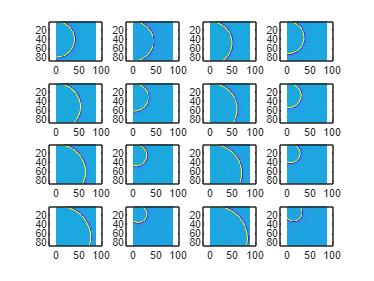

figure,
for i = 1:16
    subplot(4,4,i),imagesc(squeeze(a(i,:,:))),axis equal
end